close all; clear all; clc; warning off

Dataset = readtable('Dados/PRSA_Data_Aotizhongxin_20130301-20170228');
opts = detectImportOptions('Dados/PRSA_Data_Aotizhongxin_20130301-20170228');
disp([opts.VariableNames' opts.VariableTypes'])

    {'No'     }    {'double'}
    {'year'   }    {'double'}
    {'month'  }    {'double'}
    {'day'    }    {'double'}
    {'hour'   }    {'double'}
    {'PM2_5'  }    {'double'}
    {'PM10'   }    {'double'}
    {'SO2'    }    {'double'}
    {'NO2'    }    {'double'}
    {'CO'     }    {'double'}
    {'O3'     }    {'double'}
    {'TEMP'   }    {'double'}
    {'PRES'   }    {'double'}
    {'DEWP'   }    {'double'}
    {'RAIN'   }    {'double'}
    {'wd'     }    {'char'  }
    {'WSPM'   }    {'double'}
    {'station'}    {'char'  }





Dataset = rmmissing(Dataset);
% Escolher as entradas numericas e a saida
T_inputs = Dataset(:, [3, 4, 5, 6, 7, 8, 9, 10, 11, 13, 14, 15, 17]); % Entradas
T_targets = Dataset.TEMP'; % Saidas

% Definir as entradas e as saidas da rede
inputs = table2array(T_inputs)'; % Entradas
targets = T_targets; % Saidas

size(inputs)  % 15 395

ans =           14       31876


size(targets) % 1  395

ans =            1       31876


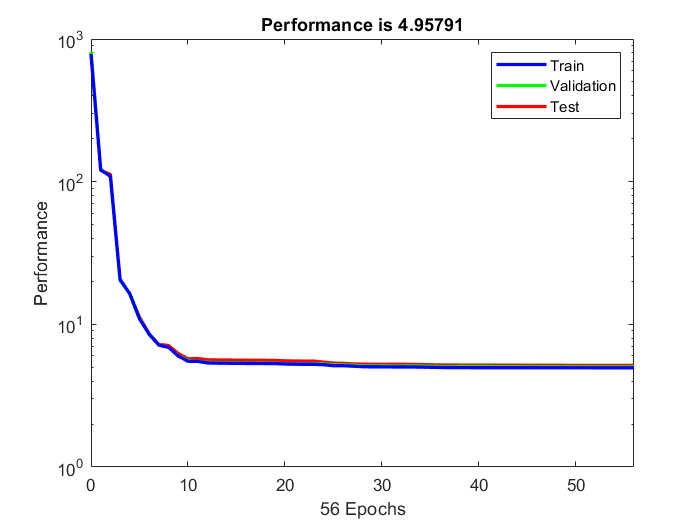



% inicializar a rede
hiddenLayerSize = 10;
net = feedforwardnet(hiddenLayerSize);
%[DUVIDA] Como alterar os parametros da rede? 
%[DUVIDA] É melhor usar feeedforward ou newrbe?

% definir datasets de treino, validação e teste
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

%treinar a rede
[net, tr] = train(net, inputs, targets);

% Avaliar o desempenho
plotperf(tr)

%[DUVIDA] Como saber a métrica usada na performance deste dataset?

disp(['Performance no treino: ' num2str(tr.best_perf) ' MSE' ])

Performance no treino: 4.9613 MSE


disp(['Performance na validacao: ' num2str(tr.best_vperf) ' MSE' ])

Performance na validacao: 5.0337 MSE


disp(['Performance no teste: ' num2str(tr.best_tperf) ' MSE' ])

Performance no teste: 5.1578 MSE



predicted = net(inputs);
target = targets;
RMSE = sqrt(mean(( predicted  - target).^2)) % V1 = target, V2 = predicted

RMSE = 2.2364


R = corrcoef(predicted, target); % R2 = R^2
%[DUVIDA] R2 é suposto dar matriz?
R2 = R*R

R2 =     1.9613    1.9609
    1.9609    1.9613



% [DUVIDA] Quero ter os dados anteriores para a rede RBF.

% Treinar uma rede neuronal RBF
% netRBF = newrb(inputs, targets); % Iniciar e treinar a rede RBF
% view(netRBF); 

